# Camera Color Calibration

*Ben Morris, 4/15/2022, Rev A*

Uses [Imatest](https://www.imatest.com/mathworks/esfr/)'s eSFR chart to calculate a color correction matrix for the current lighting conditions.

Code taken from [Matlab Documentation on Color Masking](https://www.mathworks.com/help/images/correct-colors-using-color-correction-matrix.html)

## Step 1 - Take Snapshot

Take snapshot of Imatest's [color calibration picture](https://www.imatest.com/wp-content/uploads/2022/01/extended_esfr.png)

cam = webcam(2);
preview(cam);
input('Hit enter to take a snapshot.');
I = snapshot(cam);
closePreview(cam);

Create and display an eSFR chart from the image.

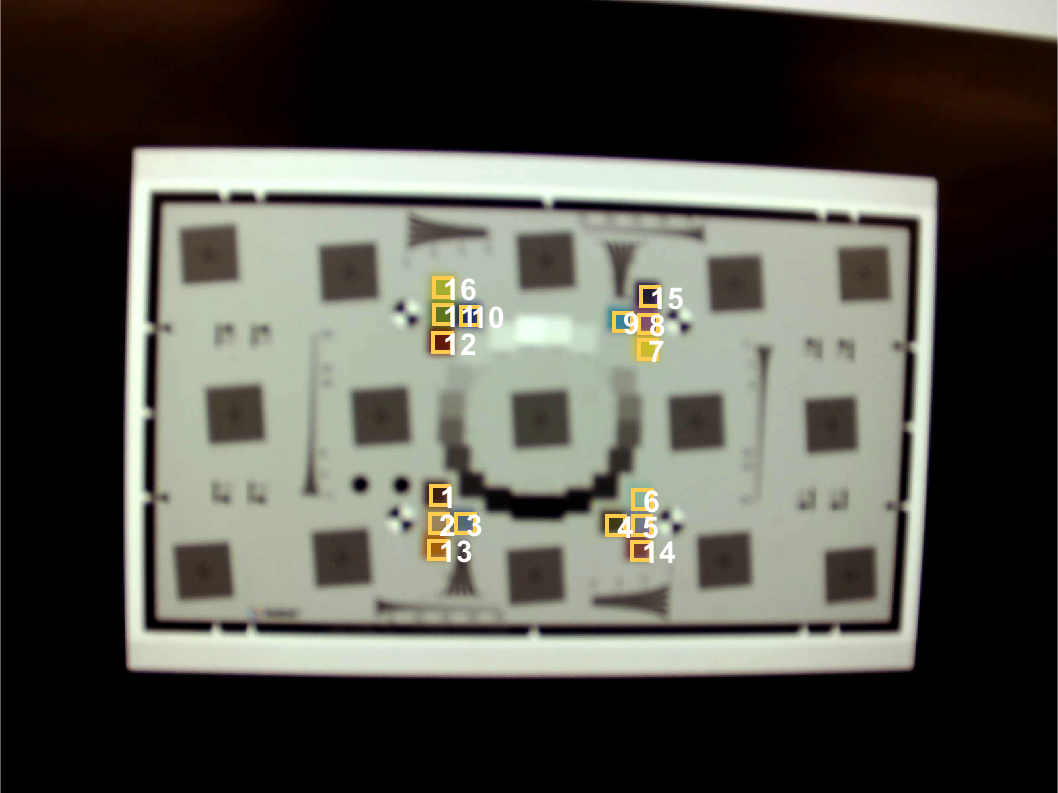

chart = esfrChart(I);
displayChart(chart,'displayEdgeROIs',false,'displayRegistrationPoints',false);

## Step 2 - Calculate Correction

`measureColor` creates a color table showing the difference between the colors. It also returns a color correction matrix that can be applied to the image to correct the color

[colorTable, ccm] = measureColor(chart);

Visualize the color table. $\Delta E$ should be close to 1 if the colors match.

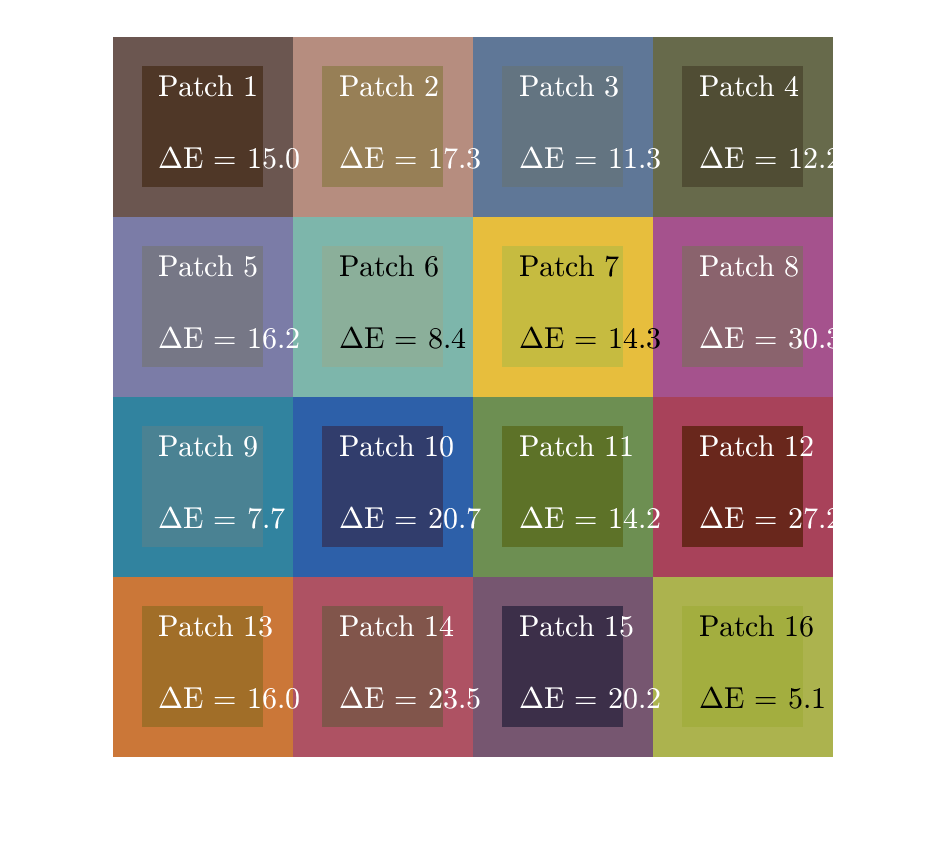

displayColorPatch(colorTable);

You can get even better color correction by better taking into account gray pixels (warning: large code block)

% Get reference to gray, convert to RGB from L*a*b*
referenceRGB = lab2rgb([chart.ReferenceColorLab; chart.ReferenceGrayLab], 'OutputType', 'uint8');

% Get mean gray value by measuring noise
noiseTable = measureNoise(chart);
measuredGrayRGB = [noiseTable.MeanIntensity_R, noiseTable.MeanIntensity_G, noiseTable.MeanIntensity_B];

% Concatenate RGB of all the patches (color & grayscale)
measuredColorRGB = [colorTable.Measured_R, colorTable.Measured_G, colorTable.Measured_B];
measuredRGB = [measuredColorRGB; measuredGrayRGB];
ccm_cc = double([measuredRGB ones(36,1)]) \ double(referenceRGB);

## Step 3 - Apply Correction

Honestly don't know how `ccw` is set up, so don't know why it's written this way. Just use it.

Color correction with just the color patches.

Icc = imapplymatrix(ccm(1:3,:)',I,ccm(4,:));
figure(1)
imshow(Icc);
title('Image with color-patch correction');

Image with both colored and gray patches:

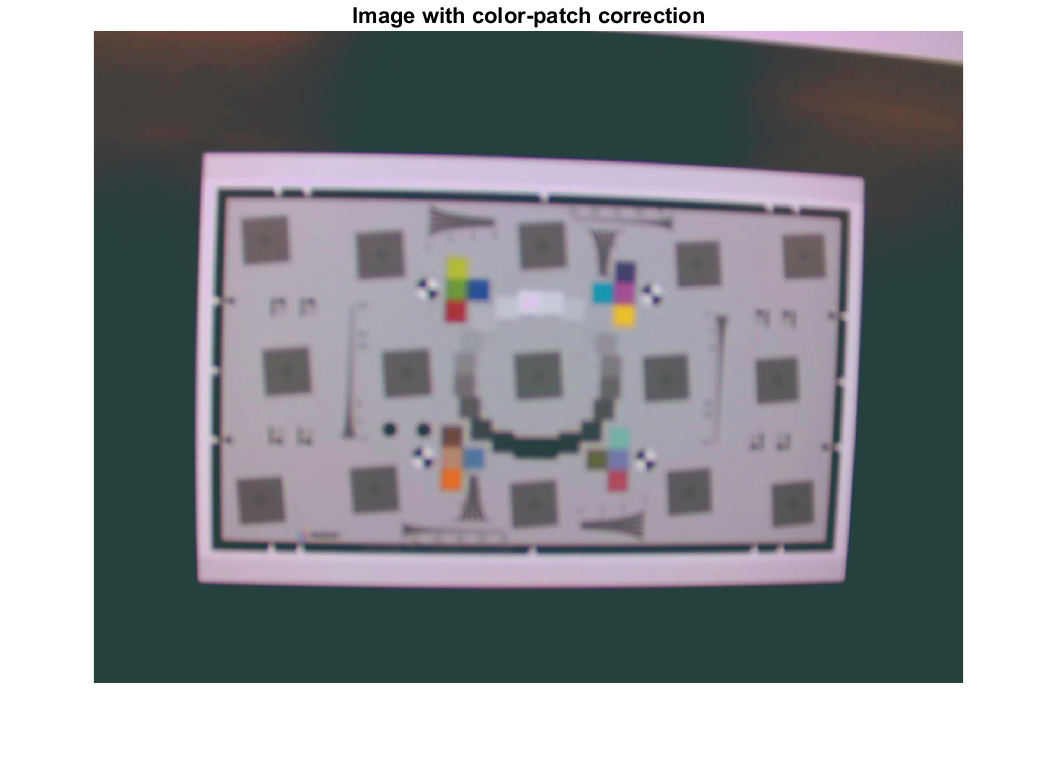

Icc2 = imapplymatrix(ccm_cc(1:3,:)',I,ccm_cc(4,:));
figure(2)
imshow(Icc2);

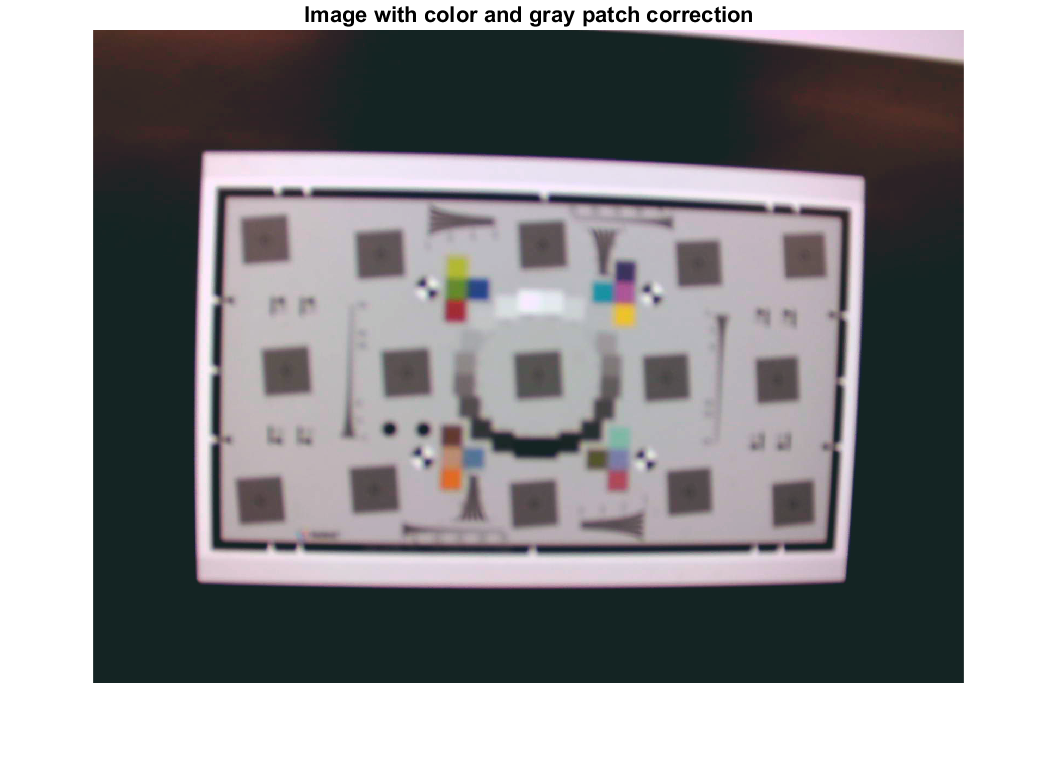

title('Image with color and gray patch correction');

Display color corrected color patch. $\Delta E$ should be much closer to 1.

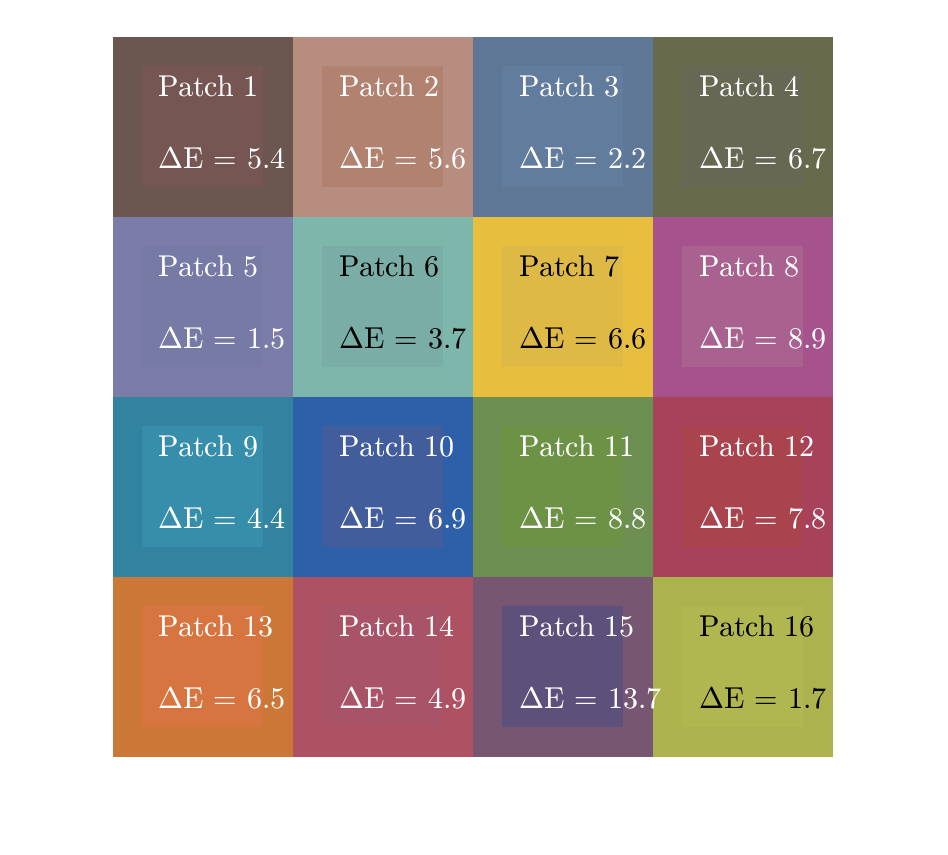

chartcc = esfrChart(Icc);
[ccColorTable, ~] = measureColor(chartcc);
displayColorPatch(ccColorTable);

Display corrected color patch for full correction

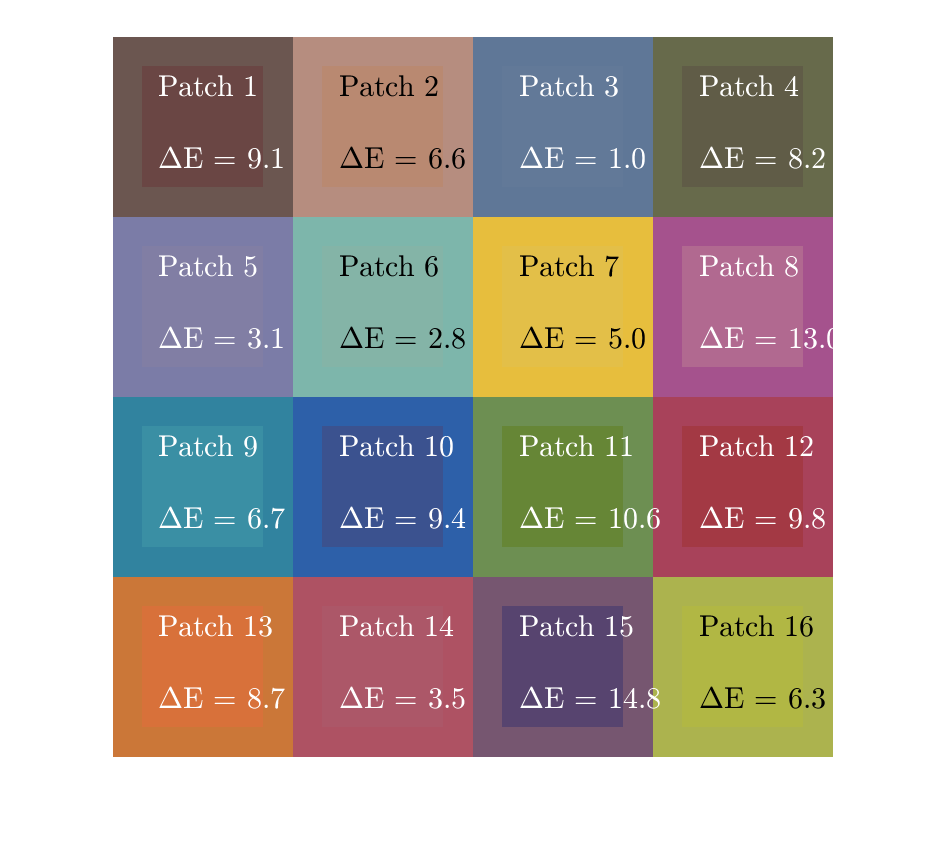

chartcc2 = esfrChart(Icc2);
[ccColorTable2, ~] = measureColor(chartcc2);
displayColorPatch(ccColorTable2);

Calculate the average $\Delta E$ for each of the three color patch tables

ogDE = mean(colorTable.Delta_E)

ogDE = 16.2285

ccDE = mean(ccColorTable.Delta_E)

ccDE = 5.9512

cc2DE = mean(ccColorTable2.Delta_E)

cc2DE = 7.4167